% truncated binomial fit (for fluorescence steps in homomultimeric proteins)

example for a hexameric protein with only fluorescent spots (#steps > 0) counted

steps      1       2     3     4     5     6

counts    83    72   17    6     1     0  (N=179)

% generate expanded data vector
n = [83; 72; 17; 6; 1;  0];
x = (1:6)'; % range of exptl data
nn = [];
for i = 1:6
    nn = [nn; ones(n(i), 1) .* i];
end

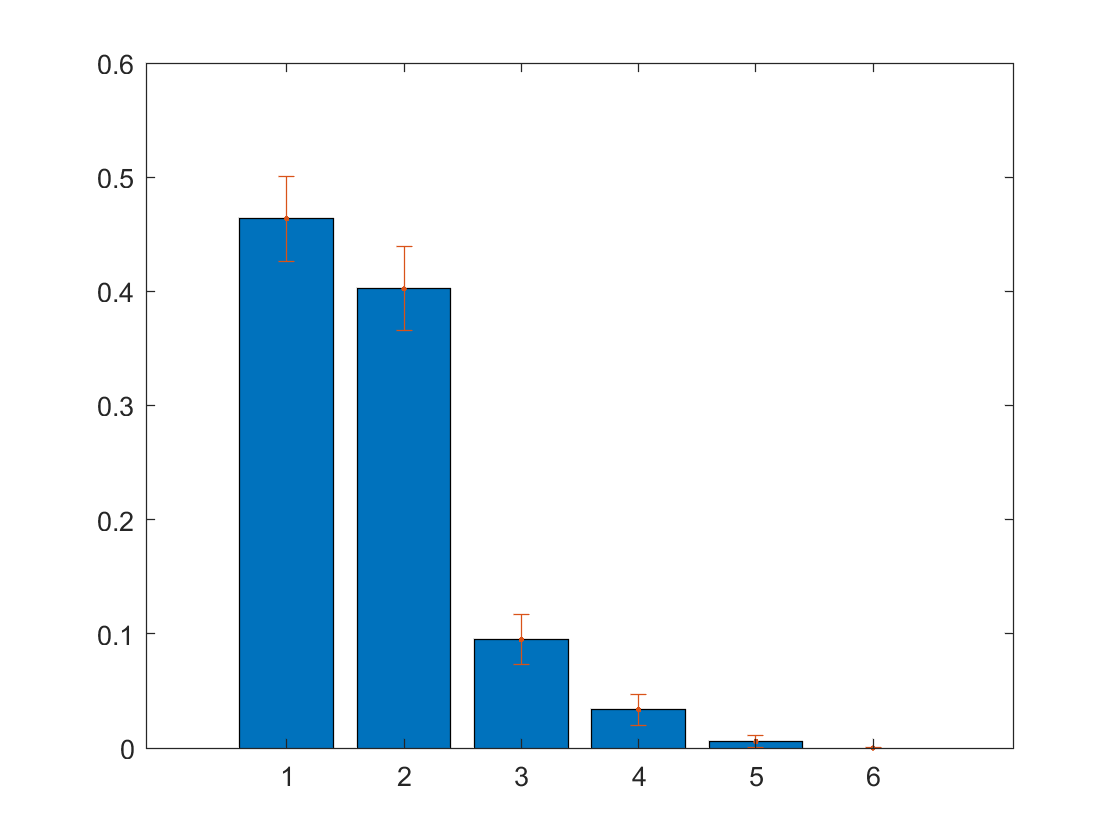

% plot data with s.e.
N = sum(n); 
p = n ./ N; % exptl prob dist
s = sqrt(N .* p .* (1 - p)) ./ N;  % exptl se
bar(x, p);
hold on
errorbar(x, p, s, '.');

% fit to a truncated binomial (truncated since molecules with zero dyes aren't detected)
f=@(x, p) pdf('Binomial', x, 6, p) ./ sum(pdf('Binomial', 1:6, 6, p));
[phat,pci] = mle(nn, 'pdf', f, 'start', 0.2)

phat = 0.2229

pci =     0.1922
    0.2536


% above line gives fraction monomers labeled and 95% CI

% calc and plot theoretical distn
x2 = 0:6;
t = pdf('Binomial', x2, 6, phat);
t = t ./ sum(t(2:7))

t =     0.2824    0.4861    0.3485    0.1333    0.0287    0.0033    0.0002


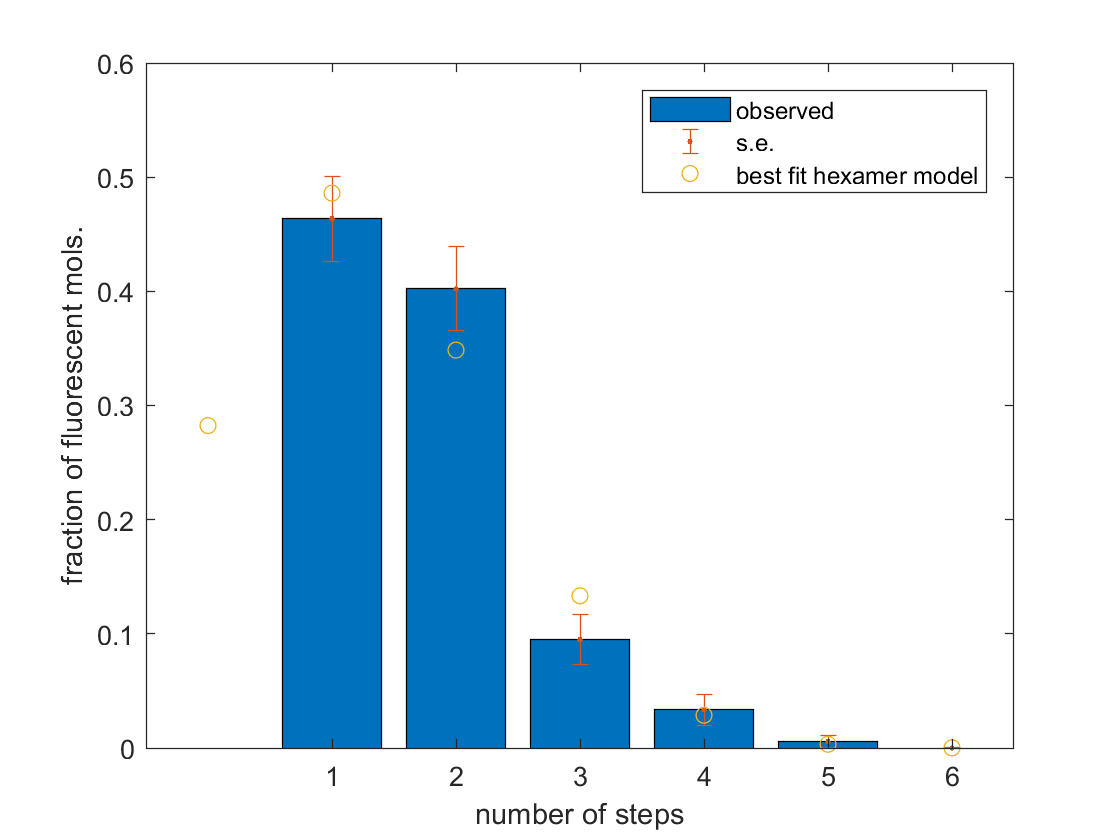

plot(x2, t, 'o') % using truncateed normalization to compare with data
hold off
xlabel('number of steps');
ylabel('fraction of fluorescent mols.')
xlim([-0.5,6.5])
legend('observed', 's.e.', 'best fit hexamer model')